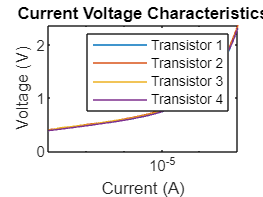

load("Experiment 1\Transistor 1\Iin1.mat");
%Iin1=Iin;
load("Experiment 1\Transistor 2\Iin2.mat");
Iin2=Iin;
load("Experiment 1\Transistor 3\Iin3.mat");
Iin3=Iin;
load("Experiment 1\Transistor 4\Iin4.mat");
Iin4=Iin;
load("Experiment 1\Transistor 1\Vout1.mat");
%Vout1=Vout;
load("Experiment 1\Transistor 2\Vout2.mat");
Vout2=Vout;
load("Experiment 1\Transistor 3\Vout3.mat");
Vout3=Vout;
load("Experiment 1\Transistor 4\Vout4.mat");
Vout4=Vout;
semilogx(Iin1,Vout1)
hold on
title("Current Voltage Characteristics")
ylabel("Voltage (V)")
xlabel("Current (A)")
semilogx(Iin2,Vout2)
semilogx(Iin3,Vout3)
semilogx(Iin4,Vout4)
legend("Transistor 1","Transistor 2","Transistor 3","Transistor 4")
hold off

clf
%Transistor 1
load("Experiment 1\Transistor 1\Iin1.mat");
load("Experiment 1\Transistor 1\Vout1.mat");
[Is1, VT1, kappa1]=ekvfit(Vout1, Iin1, 5e-4);
I1=theoretical(Vout1, VT1, kappa1, Is1);
%Transistor 2
load("Experiment 1\Transistor 2\Iin2.mat");
load("Experiment 1\Transistor 2\Vout2.mat");
[Is2, VT2, kappa2]=ekvfit(Vout2, Iin2, 5e-4);

Is2 = 1.6089e-06

VT2 = 0.5818

kappa2 = 0.7382

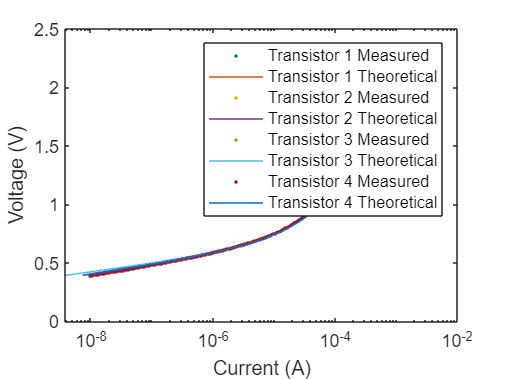

I2=theoretical(Vout2, VT2, kappa2, Is2);
%Transistor 3
load("Experiment 1\Transistor 3\Iin3.mat");
load("Experiment 1\Transistor 3\Vout3.mat");
[Is3, VT3, kappa3]=ekvfit(Vout3, Iin3, 5e-4);
I3=theoretical(Vout3, VT3, kappa3, Is3);
%Transistor 4
load("Experiment 1\Transistor 4\Iin4.mat");
load("Experiment 1\Transistor 4\Vout4.mat");
[Is4, VT4, kappa4]=ekvfit(Vout4, Iin4, 5e-4);
I4=theoretical(Vout4, VT4, kappa4, Is4);

%Transistor
semilogx(Iin1,Vout1,'.')
hold on
semilogx(I1,Vout1)
semilogx(Iin2,Vout2,'.')
semilogx(I2,Vout2)
semilogx(Iin3,Vout3,'.')
semilogx(I3,Vout3)
semilogx(Iin4,Vout4,'.')
semilogx(I4,Vout4)
ylabel("Voltage (V)")
xlabel("Current (A)")
legend("Transistor 1 Measured","Transistor 1 Theoretical","Transistor 2 Measured","Transistor 2 Theoretical","Transistor 3 Measured","Transistor 3 Theoretical","Transistor 4 Measured","Transistor 4 Theoretical")

clf
combined=[Vout1;Vout2;Vout3;Vout4]

combined =     2.3180    2.2680    2.2180    2.1700    2.1260    2.0820    2.0380    1.9960    1.9540    1.9160    1.8780    1.8400    1.8040    1.7700    1.7360    1.7040    1.6720    1.6420    1.6120    1.5800    1.5530    1.5260    1.5010    1.4760    1.4510    1.4280    1.4040    1.3820    1.3470    1.3260    1.3060    1.2860    1.2660    1.2470    1.2290    1.2110    1.1940    1.1770    1.1600    1.1440    1.1290    1.1130    1.0990    1.0840    1.0710    1.0570    1.0440    1.0320    1.0190    1.0070
    2.3280    2.2760    2.2260    2.1780    2.1320    2.0880    2.0440    2.0020    1.9600    1.9220    1.8820    1.8460    1.8100    1.7740    1.7400    1.7080    1.6760    1.6460    1.6160    1.5890    1.5620    1.5340    1.5090    1.4840    1.4590    1.4350    1.4110    1.3890    1.3540    1.3330    1.3120    1.2910    1.2710    1.2520    1.2330    1.2110    1.1930    1.1770    1.1600    1.1430    1.1280    1.1130    1.0990    1.0840    1.0710    1.0570    1.0430    1.0310    1.01

M=mean(combined)

M =     2.3255    2.2740    2.2245    2.1765    2.1310    2.0870    2.0430    2.0010    1.9590    1.9200    1.8815    1.8445    1.8085    1.7735    1.7375    1.7050    1.6735    1.6430    1.6135    1.5840    1.5570    1.5300    1.5048    1.4803    1.4552    1.4315    1.4078    1.3850    1.3502    1.3290    1.3085    1.2883    1.2683    1.2492    1.2308    1.2120    1.1945    1.1780    1.1612    1.1450    1.1295    1.1143    1.1000    1.0853    1.0720    1.0580    1.0448    1.0322    1.0198    1.0075


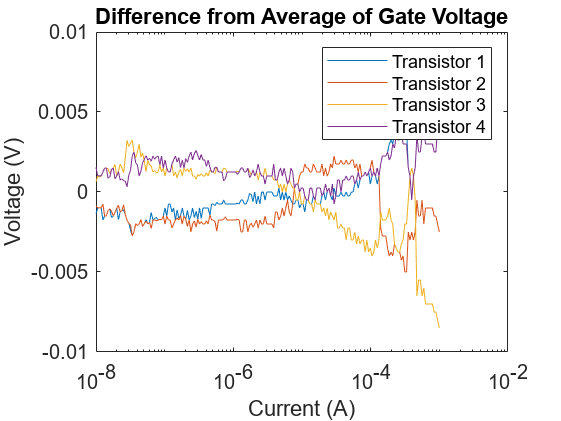

semilogx(Iin1,M-Vout1)
hold on
title("Difference from Average of Gate Voltage")
ylabel("Voltage (V)")
xlabel("Current (A)")
semilogx(Iin2,M-Vout2)
semilogx(Iin3,M-Vout3)
semilogx(Iin4,M-Vout4)
legend("Transistor 1","Transistor 2","Transistor 3","Transistor 4")
hold off

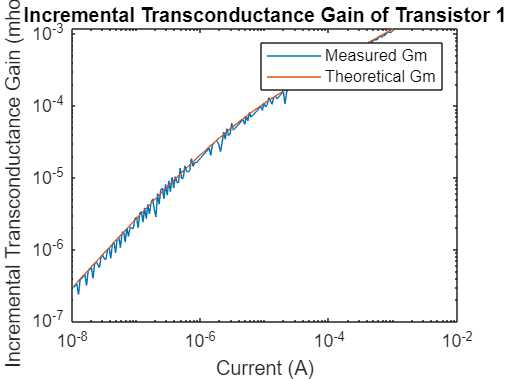

clf
gm=diff(Iin1)./diff(Vout1);
Ut=0.0258;
Iin1_short=Iin1(1,1:end-1);
gs=sqrt(Iin1_short.*Is1)/Ut.*(1-exp(-sqrt(Iin1_short./Is)));
gm_theory=kappa*gs;
loglog(Iin1_short,gm)
hold on
loglog(Iin1_short,gm_theory)
title("Incremental Transconductance Gain of Transistor 1")
ylabel("Incremental Transconductance Gain (mhos)")
xlabel("Current (A)")
legend("Measured Gm","Theoretical Gm")
hold off

function [I]=theoretical(Vout1, VT, kappa, Is)
UT=0.0258;
Vsb=0;
Vgb=Vout1;
Vdb=Vgb;
If=Is.*log(1+exp((kappa.*(Vgb-VT)-Vsb)./(2*UT))).^2;
Ir=Is.*log(1+exp((kappa.*(Vgb-VT)-Vdb)./(2*UT))).^2;
I=If-Ir;
end